Fs=1E+5

Fs = 100000

Fc=1E+3

Fc = 1000

t_offset=0

t_offset = 0

fun1=@cos

fun1 = function_handle with value:
    @cos


fun2=@sawtooth

fun2 = function_handle with value:
    @sawtooth


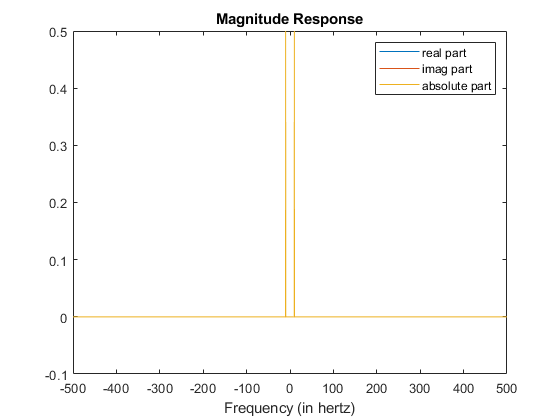

cos_fo =   -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i


[~,cos_fo]=fourierplot(fun1,Fs,Fc*2*pi,t_offset)

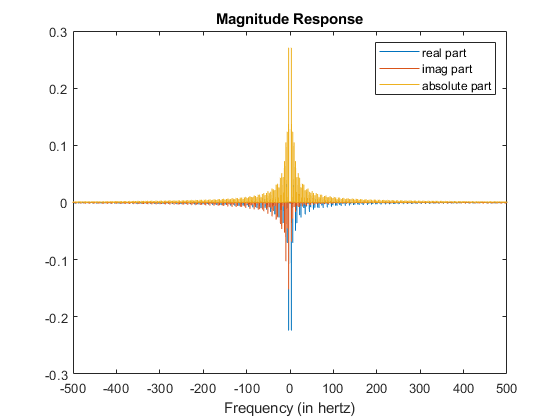

f = 	1.0e+04 *

   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000


square_fo =   -0.0085 + 0.0000i
  -0.0011 + 0.0007i
   0.0007 - 0.0009i
  -0.0001 + 0.0010i
  -0.0002 - 0.0006i
   0.0002 + 0.0002i
  -0.0001 - 0.0000i
  -0.0001 + 0.0001i
   0.0002 - 0.0002i
  -0.0001 + 0.0003i


[f,square_fo]=fourierplot(fun2,Fs,Fc*2*pi,t_offset)

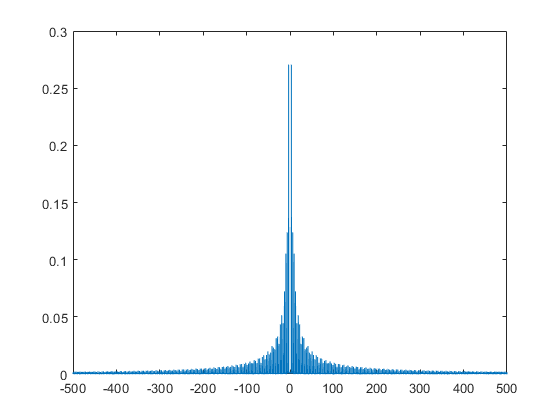

new_f=(conv(square_fo,cos_fo,'same'));
plot(f,abs(square_fo))

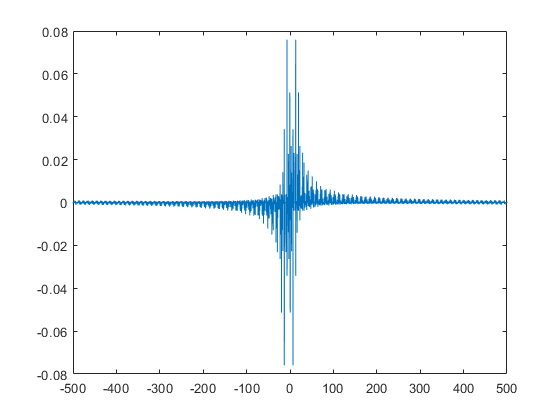

plot(f,imag(new_f))

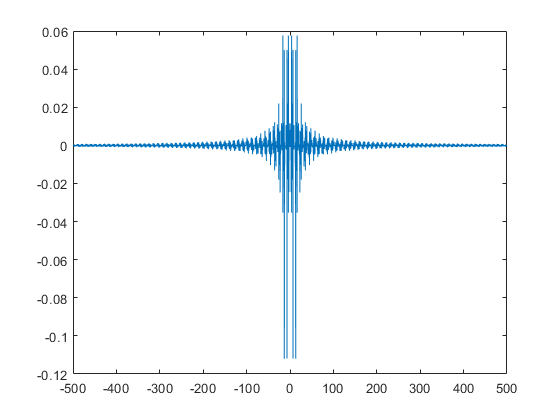

plot(f,real(new_f))

function [f_out,transformed_signal]=fourierplot(funname,Fs,Fc,t_offset)
   %%Time specifications:
   dt = 1/Fs;                     % seconds per sample
   StopTime = 100;                  % seconds
   t = (0:dt:StopTime-dt)';
   N = size(t,1);
   %%Function:
   x = funname(Fc*t-t_offset);
   %%Fourier Transform:
   X = fftshift(fft(x));
   %%Frequency specifications:
   dF = Fs/N;                      % hertz
   f = -Fs/2:dF:Fs/2-dF;           % hertz
   %%Plot the spectrum:
   figure;
   plot(f,real(X)/N,'DisplayName','real part');
   hold on
   plot(f,imag(X)/N,'DisplayName','imag part');
   plot(f,abs(X)/N,'DisplayName','absolute part')
   legend
   xlabel('Frequency (in hertz)');
   title('Magnitude Response');
   hold off
   f_out=f;
   transformed_signal=X/N;
end